# Sensor drivers

All sensors on the AR Drone 2.0 can be read using legacy C code implementations created by the Paparazzi community. All but one sensor can be read from the AR Drone 2.0's IMU board, the only extra sensor is the battery sensor.

## The legacy IMU driver 

The IMU driver is based on the navdata C source files created by the Paparazzi community, which are still under development as of march 2016. The version used in this toolbox can therefor differ from the latest version from Paparazzi but the concepts listed below will remain the same with the process through which the IMU data goes from the IMU on the drone to Simulink as shown below. The Paparazzi implementation uses the files "navdata.c" and "navdata.h". The AR Toolbox versions of these files have been adjusted to work without external Paparazzi files and are placed in the AR Toolbox as "IMU_Navdata.c" and "IMU_Navdata.h".

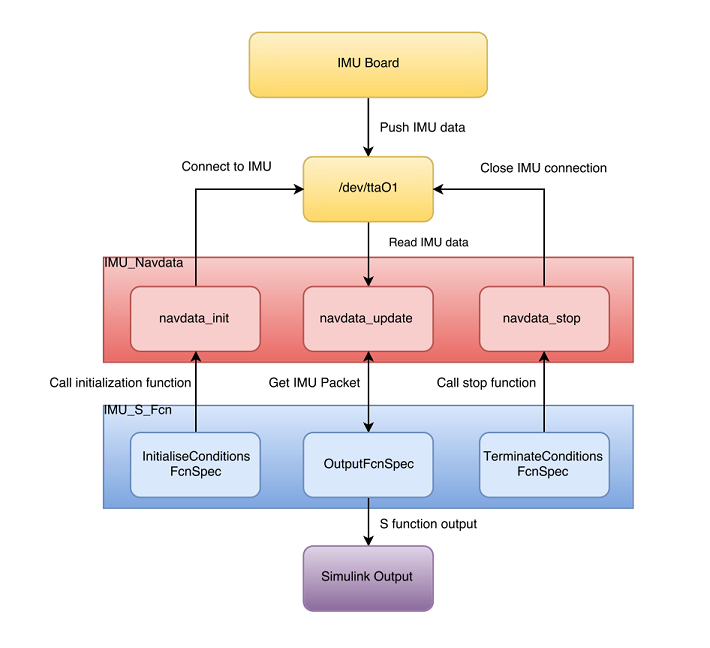

## The IMU packet data structure

The IMU outputs data in a specific format. In order to use this data format in the C code driver it is defined as the IMU_Packet struct in IMU_Navdata.h. This same data struct forms the output of the Simulink block and as such a Simulink bus object is created which uses IMU_Navdata.h as the header file to define the signals by name and type.

 IMU_Packets contains the following fields:

- taille                            unsigned int 16        Size of the IMU Packet

- nu_trame                    unsigned int 16        IMU Packet identifier number

- ax,ay,az                      signed int 16            Raw accelerometer data (x, y, z direction)

- vx,vy,vz                       signed int 16            Raw gyroscope data (x, y, z direction)

- temp_acc                    unsigned int 16        Accelerometer temperature

- temp_gyro                   unsigned int 16        Gyroscope temperature

- ultrasound                   unsigned int 16        Raw ultrasound data

Unused / unknown ultrasound parameters:

- us_debut_echo            unsigned int 16

- us_fin_echo                 unsigned int 16

- us_association_echo   unsigned int 16

- us_distance_echo        unsigned int 16

- us_cuve_time               unsigned int 16 

- us_curve_value            unsigned int 16

- us_curve_ref                unsigned int 16

- nb_echo                       unsigned int 16

- sum_echo                    unsigned int 32

- gradient                        signed int 16

- flag_echo_ini                unsigned int 16

Final known IMU Packet data:

- pressure                        signed int 16         Raw barometer data

- temperature_pressure   unsigned int 16     Barometer temperature

- mx,my,mz                      signed int 16         Raw magenetometer data (x, y, z direction)

- chksum                          unsigned int 16     Checksum for validating packet integrity.

## Retrieving IMU data

**Initialization**

The initialization function within the driver code opens a serial connection to /dev/ttaO1 and set the UART Baud rate to 460800 bits per second and is defined as:

(int IMU_Navdata_init())

A seperate thread is then created to handle reading of the IMU data. This initialization function is specified as the InitializeConditionsFcnSpec within the legacy code tool such that it is called before the program receives the 'Start' command from the Simulink PC. If the process is unsuccessful the legacy function will return a non zero value which will cause the wrapper function to print an error.

**Update**

With the thread set up the IMU data can be read at will using the update function: 

(int IMU_Navdata_update())

This function calls a sub function which reads from the IMU connection:

(void Acquire_Navdata_Bytes())

- If the received packet starts with a NAVDATA start byte the IMU data at /dev/ttaO1 is flushed.

- The checksum is then calculated to verify the packet integrity.